I = imread('pic/flower.jpg');
I = double(I);
T = dctmtx(8);
dct = @(block_struct) T * block_struct.data * T';
% this would pad image with zeros
B = blockproc(I,[8 8],dct);

k = 8;
seg = img_k_means(I, k);
[Counts, gVar] = k_means_process(I, seg, k);

upper = 0.6;
lower = 0.25;
[Bq q_ref] = myQ(B, upper, lower, seg, Counts, gVar);
nnz(Bq)

ans = 22192

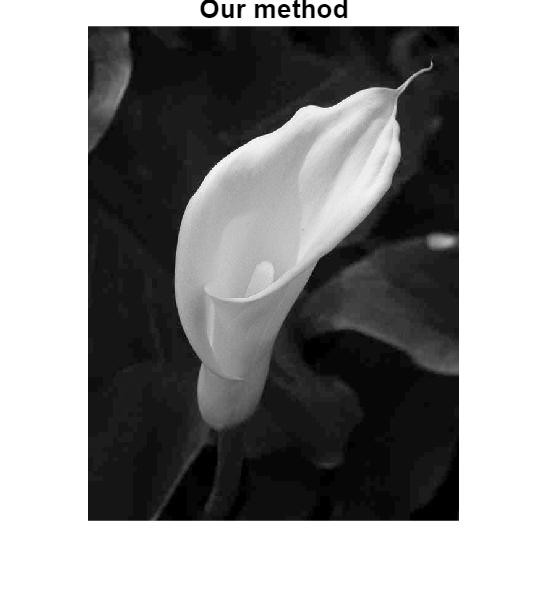

idct = @(block_struct) T' * block_struct.data * T;
Iq = blockproc(Bq,[8 8],idct);
imshow(Iq,[0 255]); truesize; title("Our method");

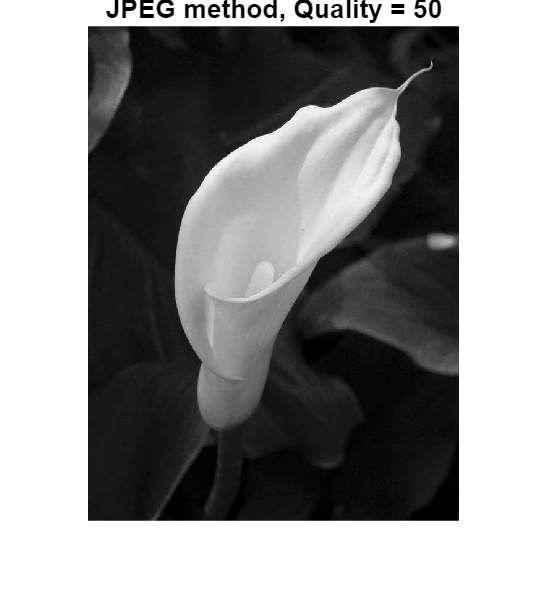

Q_50 = q_factor(50);
aq = blockproc(B,[8 8], @(block_struct) Q_50.* round((block_struct.data) ./ Q_50) );
idct2 = @(block_struct) T' * block_struct.data * T;
Iq50 = blockproc(aq,[8 8],idct2);
imshow(Iq50,[0 255]); truesize; title("JPEG method, Quality = 50");

nnz(aq)

ans = 21101

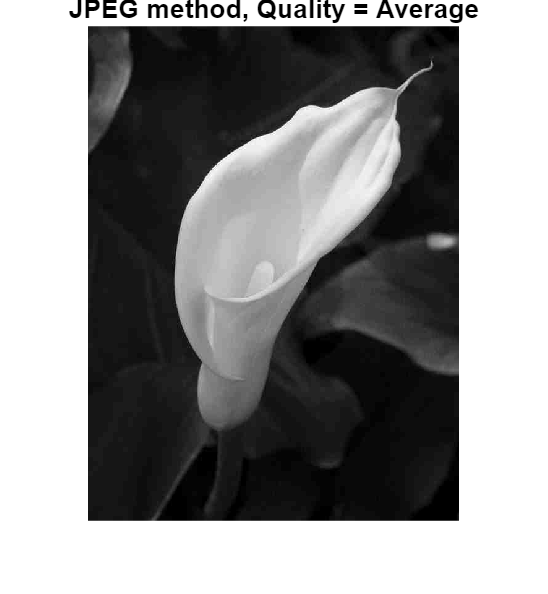

Q_avg = q_factor(mean(q_ref, 'all'));
aq = blockproc(B,[8 8], @(block_struct) Q_avg.* round((block_struct.data) ./ Q_avg) );
idct2 = @(block_struct) T' * block_struct.data * T;
Iq_avg = blockproc(aq,[8 8],idct2);
imshow(Iq_avg,[0 255]); truesize; title("JPEG method, Quality = Average");

nnz(aq)

ans = 13152

% Q_avg = q_factor(51.79);
% aq = blockproc(B,[8 8], @(block_struct) Q_avg.* round((block_struct.data) ./ Q_avg) );
% idct2 = @(block_struct) T' * block_struct.data * T;
% Iq_avg = blockproc(aq,[8 8],idct2);
% imshow(Iq_avg,[0 255]); truesize; title("JPEG method, Quality = Average");
% nnz(aq)

diff1 = log10(norm(I - Iq, 'fro')^2)

diff1 = 6.6178

diffq50 = log10(norm(I - Iq50, 'fro')^2)

diffq50 = 6.3422

diffq_avg = log10(norm(I - Iq_avg, 'fro')^2)

diffq_avg = 6.6219

% we notice that we cannot not just variance as the indicator since for the
% part with light verical or horizontal pattern, it's very sensitive to
% human eye but since the color difference is low, our algorithm
% categorize it as block with low information and thus apply low quality
% factor.

% suggestions: adaptively split the image into different blocks
% such as border detection

% there are too much information by using the variance of the whole image
% probably use soft split / hard split of image
% 
% imagesc(clustered_image);  % Use imagesc to display the clustered labels
% title('Segmented Image');
% axis equal tight off;  % Adjust axis properties for better display
% 
% 
% % probably within each section, kind of genereate a historgram of them
% % and count number of bins larger than certain amount
% % to detect if there's a pattern
% % if there is, use a higher quality factor
% 
% % on the border of two section, always use a default quality factor
% 
% % Silhouette Analysis  could be used to auto choosing number segements in
% % an image

% % Detect vertical edges
% verticalEdges = edge(I, 'Canny',[0.25, 0.4], 'vertical');
% % Detect horizontal edges
% horizontalEdges = edge(I, 'Canny',[0.25, 0.4], 'horizontal');
% 
% % Display the results
% figure;
% subplot(1, 2, 1);
% imshow(verticalEdges);
% title('Vertical Edges');
% 
% subplot(1, 2, 2);
% imshow(horizontalEdges);
% title('Horizontal Edges');